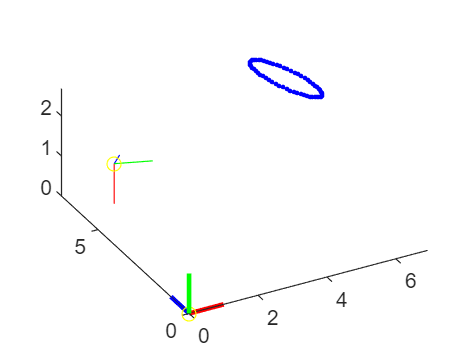

A = readmatrix('A1.csv');

focalLength = 1/34;
%position of the camera
cc = [1 6 1];
%axis of the camera
vx = [1 6 0];
vy = [1.34 6.34 1];
vz = [1.94 5.66 1]; 

%camera reference frame
p3 = plot3(cc(1),cc(2),cc(3),'o');
p3.Color = 'Yellow';
hold on
p3 = plot3([cc(1) vx(1)],[cc(2) vx(2)],[cc(3) vx(3)], '-');
p3.Color = 'Red';
hold on
p3 = plot3([cc(1) vy(1)],[cc(2) vy(2)],[cc(3) vy(3)], '-');
p3.Color = 'Blue';
hold on
p3 = plot3([cc(1) vz(1)],[cc(2) vz(2)],[cc(3) vz(3)], '-');
p3.Color = 'Green';
hold on
%world reference frame 
p3 = plot3(0,0,0,'o');
p3.Color = 'Yellow';
hold on
p3 = plot3([0 1],[0 0],[0 0], '-');
p3.Color = 'Red';
p3.LineWidth =2;
hold on
p3 = plot3([0 0],[0 1],[0 0], '-');
p3.Color = 'Blue';
p3.LineWidth =2;
hold on
p3 = plot3([0 0],[0 0],[0 1], '-');
p3.Color = 'Green';
p3.LineWidth =2;
hold on
for i = 1 : 63
p3 = plot3(A(1,i),A(2,i),A(3,i),'.');
p3.Color = 'Blue';
end
%view([0 180]);

hold off

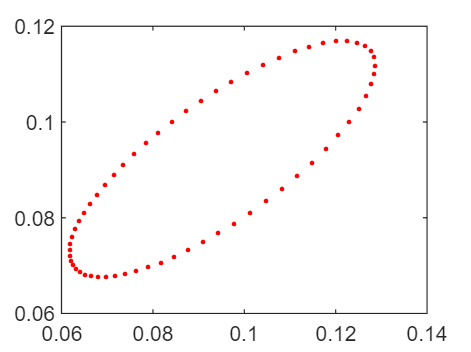



for i = 1 : 63

aX(i) = A(1,i)/(34*A(3,i));
aY(i) = A(2,i)/(34*A(3,i));

p = plot(aX(i),aY(i),'.');
p.Color = 'Red';

hold on

end